# Meet the EMG data

Lily Jiang

10/16/2023

Neurotech

In exampleEMGdata30trials.mat, you have been given some EMG data. We'll call the measurement "adjusted voltage".

These data have been "preprocessed" for you. The data started as a long stream of 4 channels (electrodes) of data. They were high pass filtered above 5 Hz and then chopped up into 30 separate Trials.

Fs is the sampling frequency (how many times per second a datapoint is recorded). actualFs is 1 / (the average of the time between each sample from the data).  It's okay for us to just assume that the standard sampling frequency is correct enough if these are close, but the value is here to show us that sampling rate is not perfect.

The labels are 1 (rock), 2 (paper), 3 (scissors). The size of the labels vector should match the number of trials. We can make a string array to store these labels. 

load("exampleEMGdata30trials.mat")
label_rps = string(["rock","paper","scissors"]);

label_rps = 1×3 string array
    "rock"    "paper"    "scissors"


The following set of questions and exercises are intended to walk you through making sense of the data. 

Using the size function, you can see that the data has 3 dimensions (channels x timepoints x trials). 

#### Exercise: Make a time vector time_ms that starts at zero and shows the time of each trial in milliseconds. 

You can use Fs or actualFs, whichever you prefer.

% 1000 samples per 1 second = 1 sample per 1 ms
time_ms = 0:1399;

#### Exercise: Make a plot of the data for any single channel (ch) and any single trial (tr) versus time_ms. Include axis labels and a title that indicates (with a word) which condition this is from (rock, paper, or scissors). 

Check for multiple channels and trials by changing the values of ch and tr. 

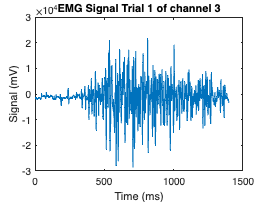

ch = 3;
tr = 1;

plot(time_ms, dataChTimeTr(ch, :, tr));
title("EMG Signal Trial " + tr + " of Channel " + ch);
xlabel("Time (ms)");
ylabel("Signal (mV)");

You should see a squiggly line. 

#### Exercise: Make plot that shows all of the "rock" trials for some channel (ch).

Each trial should be a line on the same graph. Be sure to label. It may be useful later to create a variable called cond, which indicates which condition (e.g., 1 for rock). 

You will need to use the squeeze() function to make the dimensions the proper size for plotting so you can tell Matlab to ignore the extra dimensions. I suggest that you store the data you are about to plot in a variable called cond_signals  (for condition signals).

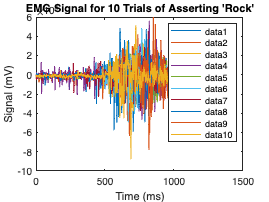

ch = 1; % channel
cond = 1; % condition (1 = rock, 2 = paper, 3 = scissors)

type = find(labels == cond);

cond_signals = dataChTimeTr(ch, :, type);
cond_signals_squeezed = squeeze(cond_signals);
plot(time_ms, cond_signals_squeezed);
title("EMG Signal for 10 Trials of Asserting 'Rock'");
xlabel("Time (ms)");
ylabel("Signal (mV)");
legend();

#### Exercise: Make a grid of plots with a row for each condition (e.g. rock) and a column for each channel (1-4).  Each plot should contain all the trials for that condition as an image. 

The x-axis should be the timepoints and the y-axis should be trial number. The colors should represent the adjusted voltage. The title should indicate the channel number and condition.

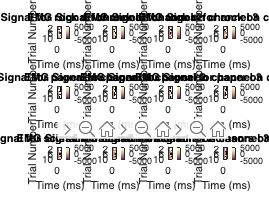

numCond = length(label_names);
numCh = 4;

for cond = 1:numCond
    for ch = 1:4
        type = find(labels == cond);

        cond_signals = dataChTimeTr(ch, :, type);
        cond_signals_squeezed = squeeze(cond_signals);

        subplot(numCond,numCh,(cond-1)*numCh + ch);
        imagesc(time_ms, 1:10, cond_signals_squeezed');

        title("EMG Signal for " + label_rps(cond) + " on channel " + ch);
        xlabel("Time (ms)");
        ylabel("Trial Number");
        colorbar; clim([-5000 5000]); colormap('pink');
    end
end

Pop the figure out of the Matlab notebook window and make it full screen so you can make better observations.

#### Exercise: Write at least 3 observations about these plots. What do you generally observe about the change in signal (color) over time?  Do all trials look the same? Can you observe any differences between the conditions in a channel?

- At around 600 ms (approximate average), there is a pretty obvious and dramatic shift across all plots from a negative signal to a more positive signal

- The positive signals aren't consistent and seem to "skip" (short blocks of white spaced by blocks of pink color), whereas the negative signal at the beginnings are much more consistently negative as evidenced by the constant pink color

- Paper has a more "clear" positive signal, meaning that when I look at the plots, the subplots for paper have a lot more white than rock or scissors.

## Feature extraction

In Part 1 of this course, we started to learn about feature extraction. With the fMRI data, we extracted an average value of different brain regions (r1, r2) and used those mean as our features. 

With EMG data, we have lots of options for interesting features to use. For now, we will just meet one: variance.

You may have observed that the signals above were squiggly lines, but perhaps some made bigger squiggles than others. 

Let's look at the very first plot we made, but instead of a line, we'll mark each data point as a dot.

We'll also add a red line that is the mean value. 

ch = 3;
tr = 1;
one_signal = dataChTimeTr(ch,:,tr);
mean_value = mean(one_signal)

mean_value = -1.2879e+03

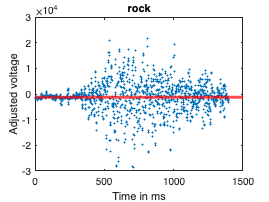

figure
plot(time_ms, one_signal,'.'); hold on;
yline(mean_value,'r','LineWidth',3);
xlabel("Time in ms"); ylabel("Adjusted voltage"); title(label_rps(labels(tr)));

The variance is the average squared distance between each blue dot and the red line. The square root of the variance is the standard deviation. We can use the variance a measure of how much variability there is in our data (how far away the datapoints tend to be from the mean)^2.

#### Exercise: Calculate the variance among the timepoints for each trial and channel.

Do this in one line of code.

variance = squeeze(var(dataChTimeTr, 0, 2));

#### Exercise: Make 3 histograms of the variance on the same figure, one for each condition. Set channel to a variable you can change, but you only need to show one channel at a time.

I suggest you use:

histogram(mydata, 'BinEdges', bins_for_hist)

in order to get bins that are the same size across your conditions.

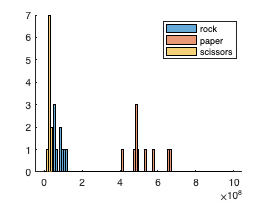

bins_for_hist = 0:10^7:10^9;

figure;
hold on;
histogram(variance(1, find(labels == 1)), 'BinEdges', bins_for_hist);
histogram(variance(2, find(labels == 2)), 'BinEdges', bins_for_hist);
histogram(variance(3, find(labels == 3)), 'BinEdges', bins_for_hist);
legend(label_rps);
hold off;

#### Exercise: What do you observe about the variance histogram? What does this tell you about how easy or difficult it might be to build a rock, paper, scissors classifier using only this feature?

It's pretty clearly sectioned between the three classifiers; scissors has the lowest variance, paper has a notably high variance, and rock is between the two but is similar to scissors.

Based on this histogram, it seems like it would not be difficult at all to build a classifier based on variance! However, I could foresee mixups between rock and scissors that would affect the accuracy.